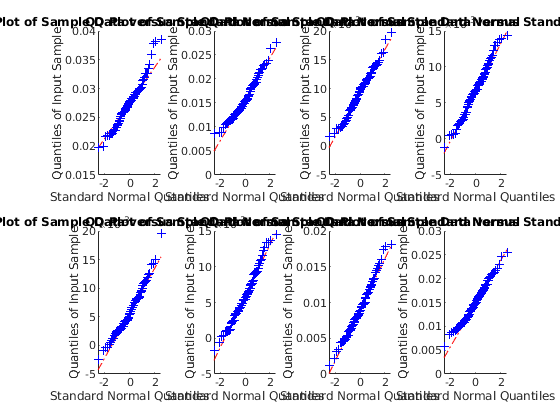

G = importdata("G_analytic.csv");
sim1=[];
sim2=[];
f=figure;
last =81;
for s = [0,8,16,24,32,40,48,56]
    tmp=importdata("correlations"+int2str(s)+".csv");
    sim1=[sim1;tmp(1:last)];
   % sim2=[sim2;importdata("correlations"+int2str(s+1)+".csv")];
    subplot(2,4,s/8+1)
    qqplot(sim1(s/8+1,:))
end

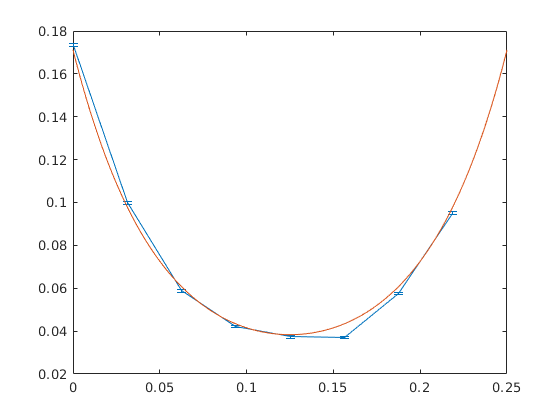

figure
mcg=mean(sim1,2);
mcv=var(sim1,1,2);
factor=2*pi;
mcv=mcv*(factor^2);
mcg=mcg*factor;
tau=linspace(0,0.25*(length(mcg)-1)/length(mcg),length(mcg));

errorbar(tau,mcg,mcv);
hold on

% mcg=mean(sim2,2);
% mcv=var(sim2,1,2);
% mcv=mcv/(factor^2);
% mcg=mcg/factor;
% tau=linspace(0.25/14,0.25*(length(mcg)-1)/length(mcg)+0.25/14,length(mcg));
% errorbar(tau,mcg,mcv);

plot(linspace(0,0.25,length(G)),G/2/pi)